# Diseño - Espacio de Estados - Qball

%clear all, close all, clc

% Constantes
m = 1.79;      g = 9.77412;
Ix = 0.03;     Iy = 0.03;
Iz = 0.04;     T = 0.01;

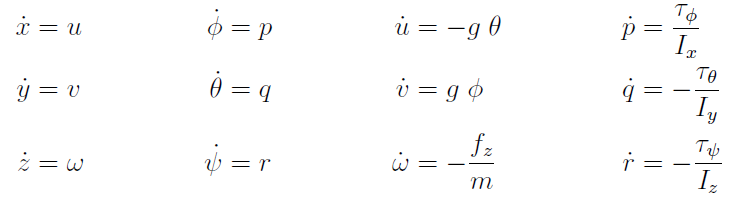

A =  [0 0 0 0  0 0 1 0 0 0 0 0 ;
      0 0 0 0  0 0 0 1 0 0 0 0 ;
      0 0 0 0  0 0 0 0 1 0 0 0 ;
      0 0 0 0  0 0 0 0 0 1 0 0 ;
      0 0 0 0  0 0 0 0 0 0 1 0 ;
      0 0 0 0  0 0 0 0 0 0 0 1 ;
      0 0 0 0 -g 0 0 0 0 0 0 0 ;
      0 0 0 g  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ];

B =  [0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      -1/m 0 0 0;
      0 1/Ix 0 0;
      0 0 -1/Iy 0;
      0 0 0 -1/Iz];

C =  [1 0 0 0 0 0 0 0 0 0 0 0 ;
      0 1 0 0 0 0 0 0 0 0 0 0 ;
      0 0 1 0 0 0 0 0 0 0 0 0 ;
      0 0 0 0 0 1 0 0 0 0 0 0 ];

D = zeros(12,4);

Aux1 = zeros(4,4);
Aux2 = zeros(12,4);

#### Verificando controlabilidad:

M = [B A*B A^2*B A^3*B A^4*B A^5*B A^6*B A^7*B A^8*B A^9*B A^10*B A^11*B ];
rank(M)

ans = 12


Mcc = [B     A;
       Aux1 -C];
rank(Mcc)

ans = 16

det(Mcc)

ans = -1.4825e+06

#### Definición del sistema ampliado:

Abar = [ A  Aux2;
        -C  Aux1];

Bbar = [B;
        Aux1];

**Polos Deseados**

pdd1 = 1.083 + 1j*1.8764;
pdd2 = 1.083 - 1j*1.8764*j;

%Pd = -[1.083+1j*1.87 1.083-1j*1.87 5 6 7 8 9 10 11 12 13 14 15 16 17 18];
%Pd = -[0.1+1j*1.87 0.1-1j*1.87 5 6 7 8 9 10 11 12 13 14 15 16 17 18];
%Pd = -[1.083+1j*1.87 1.083-1j*1.87 8 9 10 11 12 13 14 15 16 17 18 19 20 21];
%Pd = -[1.083+1j*1.87 1.083-1j*1.87 10 11 12 13 14 15 16 17 18 19 20 21 22 23];

%Ganancias más grandes 1-10
%Pd = -[1.083+1j*1.87 1.083-1j*1.87 3.1 3.2 3.3 3.4 3.5 3.6 3.7 3.8 3.9 4.0 4.1 4.2 4.3 4.4];

%Ganancias más grandes 10-100
Pd = -[1.083+1j*1.87 1.083-1j*1.87 5.1 5.2 5.3 5.4 5.5 5.6 5.7 5.8 5.9 6.0 6.1 6.2 6.3 6.4];

%Pd = -[0.183+1j*1.87 0.183-1j*1.87 5.1 5.2 5.3 5.4 5.5 5.6 5.7 5.8 5.9 6.0 6.1 6.2 6.3 6.4];

#### Definiendo la matriz de espacios nulos de los eigenvalores:

S1 = [Abar-Pd(1)*eye(16) Bbar];
S2 = [Abar-Pd(2)*eye(16) Bbar];
S3 = [Abar-Pd(3)*eye(16) Bbar];
S4 = [Abar-Pd(4)*eye(16) Bbar];
S5 = [Abar-Pd(5)*eye(16) Bbar];
S6 = [Abar-Pd(6)*eye(16) Bbar];
S7 = [Abar-Pd(7)*eye(16) Bbar];
S8 = [Abar-Pd(8)*eye(16) Bbar];
S9 = [Abar-Pd(9)*eye(16) Bbar];
S10 = [Abar-Pd(10)*eye(16) Bbar];
S11 = [Abar-Pd(11)*eye(16) Bbar];
S12 = [Abar-Pd(12)*eye(16) Bbar];
S13 = [Abar-Pd(13)*eye(16) Bbar];
S14 = [Abar-Pd(14)*eye(16) Bbar];
S15 = [Abar-Pd(15)*eye(16) Bbar];
S16 = [Abar-Pd(16)*eye(16) Bbar];

#### rref(): forma escalonada de fila reducida

a = rref(S1);
b = rref(S2);
c = rref(S3);
d = rref(S4);
e = rref(S5);
f = rref(S6);
g = rref(S7);
h = rref(S8);
i = rref(S9);
j = rref(S10);
k = rref(S11);
l = rref(S12);
m = rref(S13);
n = rref(S14);
o = rref(S15);
p = rref(S16);

#### Insertando ceros para que la matriz quede cuadrada

a1 = [a;
      zeros(4,20)];

b1 = [b;
      zeros(4,20)];

c1 = [c;
      zeros(4,20)];

d1 = [d;
      zeros(4,20)];

e1 = [e;
      zeros(4,20)];

f1 = [f;
      zeros(4,20)];

g1 = [g;
      zeros(4,20)];

h1 = [h;
      zeros(4,20)];

i1 = [i;
      zeros(4,20)];

j1 = [j;
      zeros(4,20)];

k1 = [k;
      zeros(4,20)];

l1 = [l;
      zeros(4,20)];

m1 = [m;
      zeros(4,20)];

n1 = [n;
      zeros(4,20)];

o1 = [o;
      zeros(4,20)];

p1 = [p;
      zeros(4,20)];

#### Cambiar 0's de la diagonal principal por -1

a1(17,17) = -1;
a1(18,18) = -1;
a1(19,19) = -1;
a1(20,20) = -1;
a1;

b1(17,17) = -1;
b1(18,18) = -1;
b1(19,19) = -1;
b1(20,20) = -1;
b1;

c1(17,17) = -1;
c1(18,18) = -1;
c1(19,19) = -1;
c1(20,20) = -1;
c1;

d1(17,17) = -1;
d1(18,18) = -1;
d1(19,19) = -1;
d1(20,20) = -1;
d1;

e1(17,17) = -1;
e1(18,18) = -1;
e1(19,19) = -1;
e1(20,20) = -1;
e1;

f1(17,17) = -1;
f1(18,18) = -1;
f1(19,19) = -1;
f1(20,20) = -1;
f1;

g1(17,17) = -1;
g1(18,18) = -1;
g1(19,19) = -1;
g1(20,20) = -1;
g1;

h1(17,17) = -1;
h1(18,18) = -1;
h1(19,19) = -1;
h1(20,20) = -1;
h1;

i1(17,17) = -1;
i1(18,18) = -1;
i1(19,19) = -1;
i1(20,20) = -1;
i1;

j1(17,17) = -1;
j1(18,18) = -1;
j1(19,19) = -1;
j1(20,20) = -1;
j1;

k1(17,17) = -1;
k1(18,18) = -1;
k1(19,19) = -1;
k1(20,20) = -1;
k1;

l1(17,17) = -1;
l1(18,18) = -1;
l1(19,19) = -1;
l1(20,20) = -1;
l1;

m1(17,17) = -1;
m1(18,18) = -1;
m1(19,19) = -1;
m1(20,20) = -1;
m1;

n1(17,17) = -1;
n1(18,18) = -1;
n1(19,19) = -1;
n1(20,20) = -1;
n1;

o1(17,17) = -1;
o1(18,18) = -1;
o1(19,19) = -1;
o1(20,20) = -1;
o1;

p1(17,17) = -1;
p1(18,18) = -1;
p1(19,19) = -1;
p1(20,20) = -1;
p1;

#### Construyendo las matrices Q y V

V = zeros(16,16);
Q = zeros(4,16);

V(:,1) = a1(1:16, 20);
V(:,2) = b1(1:16, 20);
V(:,3) = c1(1:16, 20);
V(:,4) = d1(1:16, 17);
V(:,5) = e1(1:16, 17);
V(:,6) = f1(1:16, 17);
V(:,7) = g1(1:16, 18);
V(:,8) = h1(1:16, 18);
V(:,9) = i1(1:16, 18);
V(:,10) = j1(1:16, 18);
V(:,11) = k1(1:16, 18);
V(:,12) = l1(1:16, 19);
V(:,13) = m1(1:16, 19);
V(:,14) = n1(1:16, 19);
V(:,15) = o1(1:16, 19);
V(:,16) = p1(1:16, 19);
V;
det(V)

ans = 3.0730e-57 + 2.1932e-41i


Q(:,1) = a1(17:20, 20);
Q(:,2) = b1(17:20, 20);
Q(:,3) = c1(17:20, 20);
Q(:,4) = d1(17:20, 17);
Q(:,5) = e1(17:20, 17);
Q(:,6) = f1(17:20, 17);
Q(:,7) = g1(17:20, 18);
Q(:,8) = h1(17:20, 18);
Q(:,9) = i1(17:20, 18);
Q(:,10) = j1(17:20, 18);
Q(:,11) = k1(17:20, 18);
Q(:,12) = l1(17:20, 19);
Q(:,13) = m1(17:20, 19);
Q(:,14) = n1(17:20, 19);
Q(:,15) = o1(17:20, 19);
Q(:,16) = p1(17:20, 19);
Q;

#### Calcular la matriz de realimentación

Kbar = Q*inv(V)

Kbar = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5083 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2846 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.6639 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.1618 + 0.0000i   0.0000 + 0.0000i  -0.0975 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0568 + 0.0000i   0.0000 + 0.0000i  -0.0086 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1844 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.2266 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1153 + 0.0000i   0.0000 + 0.0000i  -0.0731 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0093 + 0.0000i   0.0000 + 0.0000i   0.2808 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 

Ke = real(Kbar(:,1:12))

Ke =          0         0  150.8254         0         0         0         0         0   28.4610         0         0         0
         0  -16.1850         0   -9.7455         0         0         0   -5.6816         0   -0.8550         0         0
  -22.6590         0         0         0   11.5305         0   -7.3122         0         0         0    0.9300         0
         0         0         0         0         0    0.6287         0         0         0         0         0    0.2906


Ki = real(Kbar(:,13:16))

Ki =          0         0 -266.3950         0
         0   18.4395         0         0
   28.0826         0         0         0
         0         0         0   -0.9526


#### Matrices de lazo cerrado

Acl = [Abar + Bbar*Kbar]

Acl = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0100 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0100 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0100 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +

eig(Acl)

ans =   -6.4036 + 0.0000i
  -6.2842 - 0.0000i
  -6.2197 + 0.0000i
  -6.0901 - 0.0000i
  -6.0025 + 0.0000i
  -5.8997 - 0.0000i
  -5.8015 + 0.0000i
  -5.2000 + 0.0000i
  -5.6974 - 0.0000i
  -5.3000 - 0.0000i
